## Plot complete R-OCB message-level outcomes

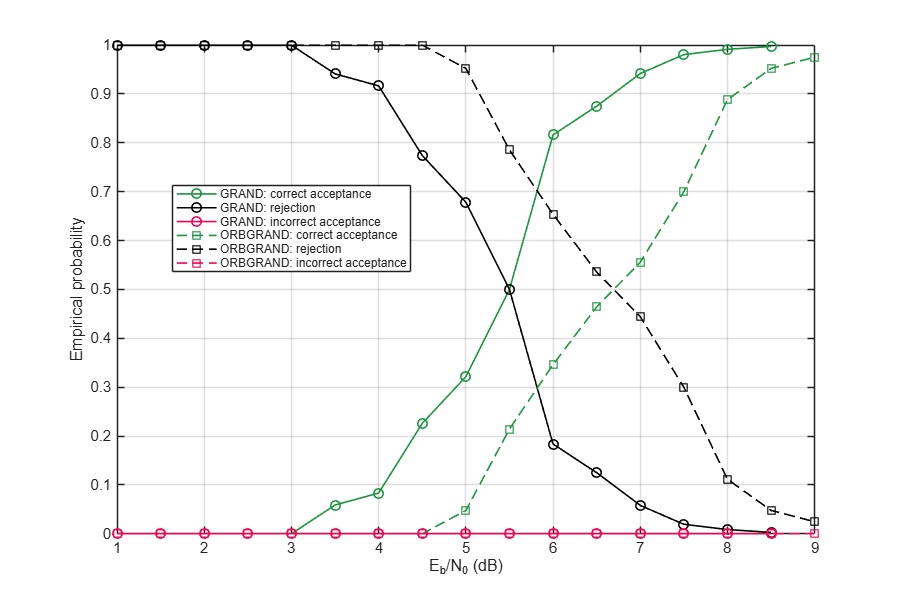


% Correct acceptance, rejection, and incorrect acceptance

clc;
clear;

% Add RESULTE folder to path
addpath('RESULTS/');
addpath('Figures/');

%% Parameters

n = 128;
% k_values = [112 116 120];
k_values = [116];

% decoders = {'GRAND', 'ORBGRAND'};
decoders = {'GRAND', 'ORBGRAND'};

% Colors:
% Green = correct acceptance
% Black = rejection
% Red   = incorrect acceptance
colors = {
    [0.1098, 0.5804, 0.2510], ...   % correct acceptance
    [0, 0, 0], ...                  % rejection
    [0.9490, 0.0235, 0.3412]        % incorrect acceptance
};

% Different line styles for GRAND and ORBGRAND
line_styles = {'-', '--'};

markers = {'o', 's'};

%% Plot each k separately

for kk = 1:length(k_values)

    k = k_values(kk);

    figure('Position', [100, 100, 900, 600]);
    hold on;

    legend_entries = {};

    for d = 1:length(decoders)

        decoder = decoders{d};

        filename = sprintf( ...
            'RESULTS/BSC_%s_ROCB_%d_%d_1.mat', ...
            decoder, n, k);

        if ~isfile(filename)
            fprintf('File not found: %s\n', filename);
            continue;
        end

        data = load(filename);

        if ~isfield(data, 'code')
            warning('No code structure in %s.', filename);
            continue;
        end

        code = data.code;

        required_fields = { ...
            'ebn0', ...
            'P_correct', ...
            'P_reject', ...
            'P_incorrect'};

        if ~all(isfield(code, required_fields))
            warning('Message-level outcome fields missing from %s.', filename);
            continue;
        end

        % Make sure all vectors have the same length
        min_len = min([ ...
            length(code.ebn0), ...
            length(code.P_correct), ...
            length(code.P_reject), ...
            length(code.P_incorrect)]);

        x = code.ebn0(1:min_len);

        P_correct   = code.P_correct(1:min_len);
        P_reject    = code.P_reject(1:min_len);
        P_incorrect = code.P_incorrect(1:min_len);

        % Sanity check
        total_probability = P_correct + P_reject + P_incorrect;

        if any(abs(total_probability - 1) > 1e-10)
            warning( ...
                '%s, k=%d: probabilities do not sum to one.', ...
                decoder, k);
        end

        %% Correct acceptance

        plot(x, P_correct, ...
            'LineStyle', line_styles{d}, ...
            'Marker', markers{d}, ...
            'Color', colors{1}, ...
            'LineWidth', 1.2, ...
            'MarkerSize', 7);

        legend_entries{end+1} = sprintf( ...
            '%s: correct acceptance', decoder);

        %% Rejection

        plot(x, P_reject, ...
            'LineStyle', line_styles{d}, ...
            'Marker', markers{d}, ...
            'Color', colors{2}, ...
            'LineWidth', 1.2, ...
            'MarkerSize', 7);

        legend_entries{end+1} = sprintf( ...
            '%s: rejection', decoder);

        %% Incorrect acceptance

        plot(x, P_incorrect, ...
            'LineStyle', line_styles{d}, ...
            'Marker', markers{d}, ...
            'Color', colors{3}, ...
            'LineWidth', 1.2, ...
            'MarkerSize', 7);

        legend_entries{end+1} = sprintf( ...
            '%s: incorrect acceptance', decoder);

    end

    %% Figure formatting

    grid on;
    box on;

    xlabel('E_b/N_0 (dB)', 'FontSize', 12);
    ylabel('Empirical probability', 'FontSize', 12);

    ylim([0 1]);

    legend(legend_entries, ...
        'Location', 'best', ...
        'FontSize', 9);

    set(gca, 'FontSize', 11);

    % title(sprintf( ...
    %     'R-OCB Complete Message Outcomes, BSC, [128,%d]', ...
    %     k), ...
    %     'FontSize', 13);

    %% Save

    fig_name = sprintf( ...
        'Figures/ROCB_Message_Outcomes_BSC_128_%d', ...
        k);

    exportgraphics(gcf, [fig_name '.pdf'], ...
        'ContentType', 'vector');

    exportgraphics(gcf, [fig_name '.png'], ...
        'Resolution', 300);

end